format long
p_2 = 1/36;
p_1 = 5/18;
q = 25/36; 
syms x
p_sym = p_2*x^3 + p_1*x^2 - x + q;
lambda_sym = solve(p_sym, x);
l_1 = double(lambda_sym(1))

l_1 =      1


l_2 = double(lambda_sym(2))

l_2 =  -12.933034373659252


l_3 = double(lambda_sym(3))

l_3 =    1.933034373659253


d_W =                    0
   2.735705242471604
   5.440130013623240
   8.084088592745367
  10.611163501192861
  12.912303986323572
  14.776631361073127
  15.797542367095796
  15.175705669585293
  11.538684492767565


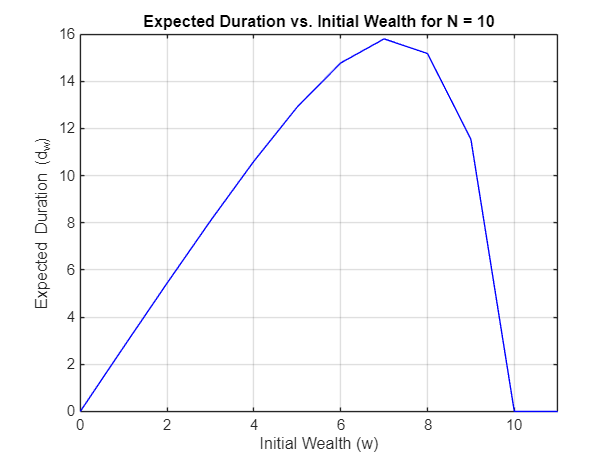

d_W = 1.0e+02 *

                   0
   0.027692307692302
   0.055384615384598
   0.083076923076884
   0.110769230769149
   0.138461538461374
   0.166153846153522
   0.193846153845521
   0.221538461537233
   0.249230769228388


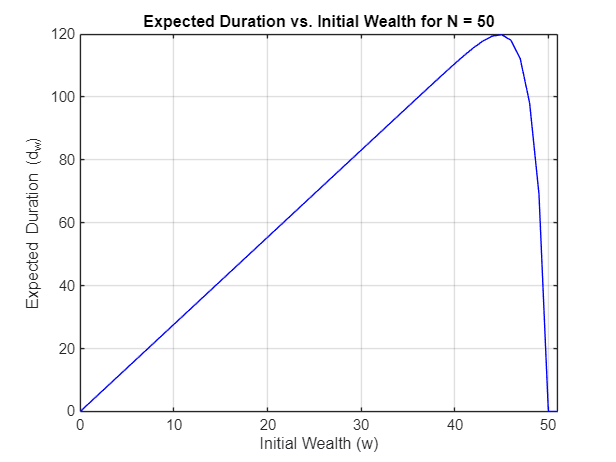

d_W = 1.0e+02 *

                   0
   0.027692307692308
   0.055384615384615
   0.083076923076923
   0.110769230769231
   0.138461538461538
   0.166153846153846
   0.193846153846154
   0.221538461538462
   0.249230769230769


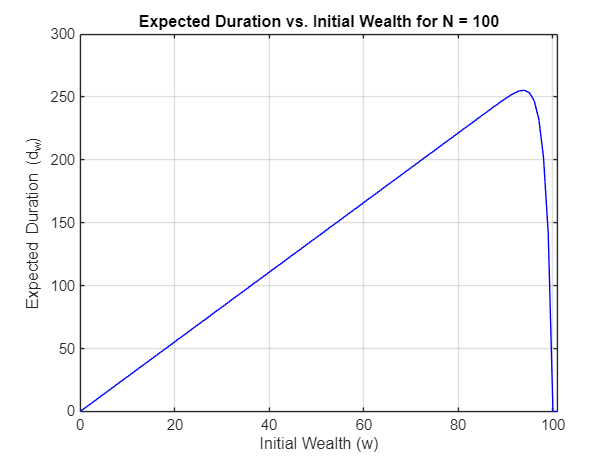


N_values = [10, 50, 100]; 
n = length(N_values);

for i = 1:n
    N = N_values(i);
    % Solve for coefficients
    syms c_1 c_2 c_3;
    [c_1, c_2, c_3] = solve( ...
    c_1 + c_2 + c_3 == 0, ...
    ((c_1)*(l_1)^(N)) + ((c_2)*(l_2)^(N)) + ((c_3)*(l_3)^(N)) - (N)/(2*p_2 + p_1 - q) == 0, ...
    ((c_1)*(l_1)^(N+1)) + ((c_2)*(l_2)^(N+1)) + ((c_3)*(l_3)^(N+1)) - (N+1)/(2*p_2 + p_1 - q) == 0);

    C1 = c_1;
    C2 = c_2;
    C3 = c_3;

    d_W = zeros(1, N+2);
    
    for W = 1:N+2
    d_W(W) = ((C1)*(l_1)^(W-1)) + ((C2)*(l_2)^(W-1)) + ((C3)*(l_3)^(W-1)) - (W-1)/(2*p_2 + p_1 - q);
    end

    d_W = double(d_W)'
    
    figure;
    plot(0:N+1, d_W, 'b', 'DisplayName', 'd_w');
    xlabel('Initial Wealth (w)');
    ylabel('Expected Duration (d_w)');
    title(['Expected Duration vs. Initial Wealth for N = ', num2str(N)]);
    grid on;
    xlim([0 N+1])

end